# Lektion 9

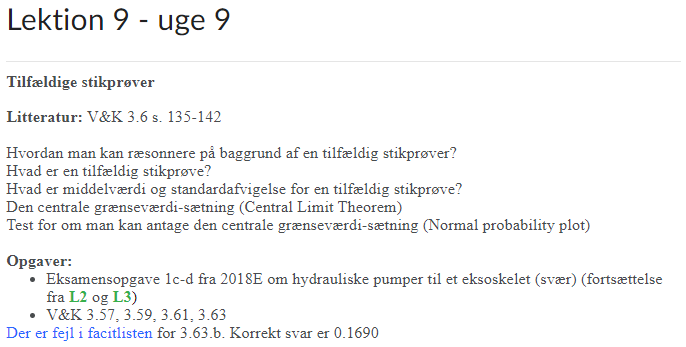

clc; clear all;

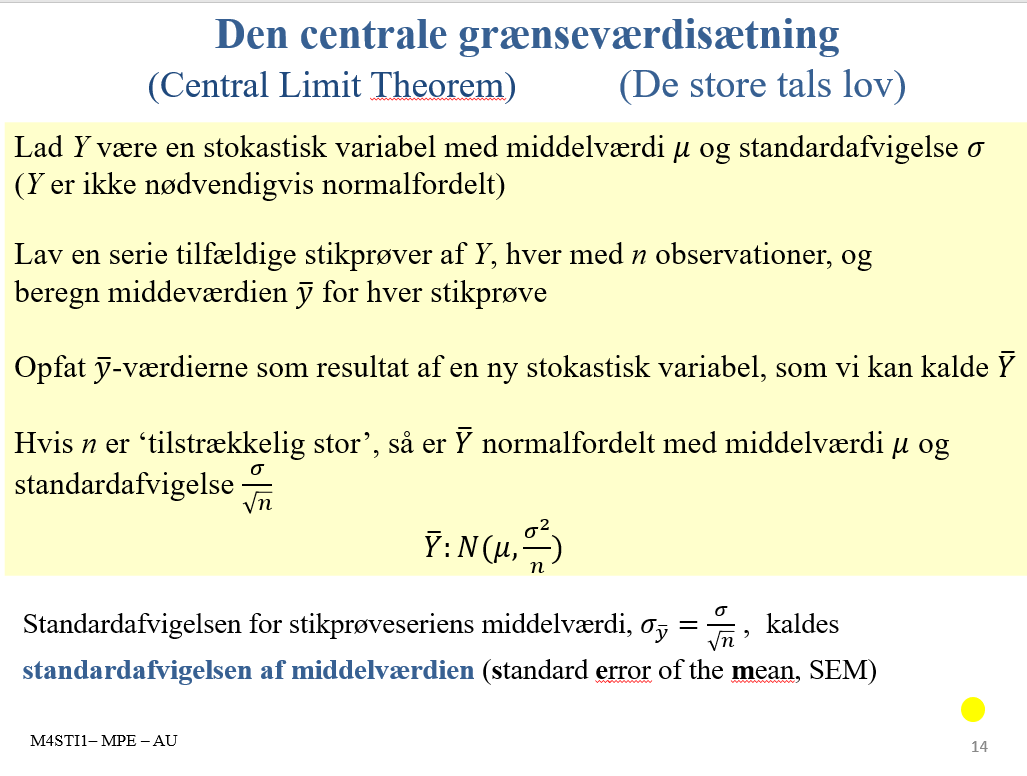

stik = 2; % Antal stikprøver
kast = 4;     % Antal terningekast / udtagelser af stikprøven

ms = [];
Y = [];

for i = 1:stik
    for j = 1:kast
        Y(i,j) = randi(6, 1)
    end
    ms(end+1) = mean(Y(i,:));
end

Y = 2

Y =      2     1


Y =      2     1     1


Y =      2     1     1     4


Y =      2     1     1     4
     1     0     0     0


Y =      2     1     1     4
     1     6     0     0


Y =      2     1     1     4
     1     6     5     0


Y =      2     1     1     4
     1     6     5     1




histogram(ms, 1:0.25:6, "Normalization","pdf")
hold on

% Den gennemsnitlige afvigelse
mean_gns = mean(ms)

mean_gns = 2.6250

stdafv = std(ms, 1)

stdafv = 0.6250

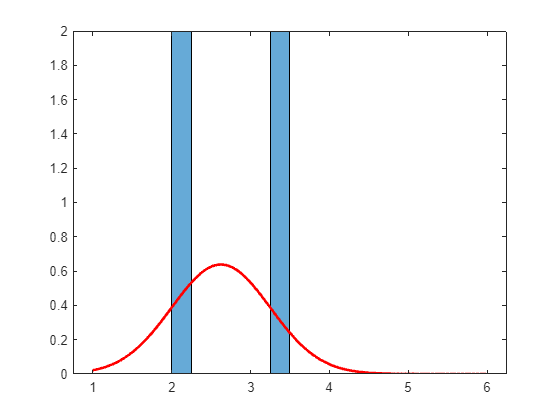


% PLotte fordelingen oveni
dist = makedist("Normal","mu",mean_gns,"sigma",stdafv);
x = 1:0.01:6;

df = pdf(dist, x);

plot(x, df, Color="red", LineStyle="-", LineWidth=2)
hold off

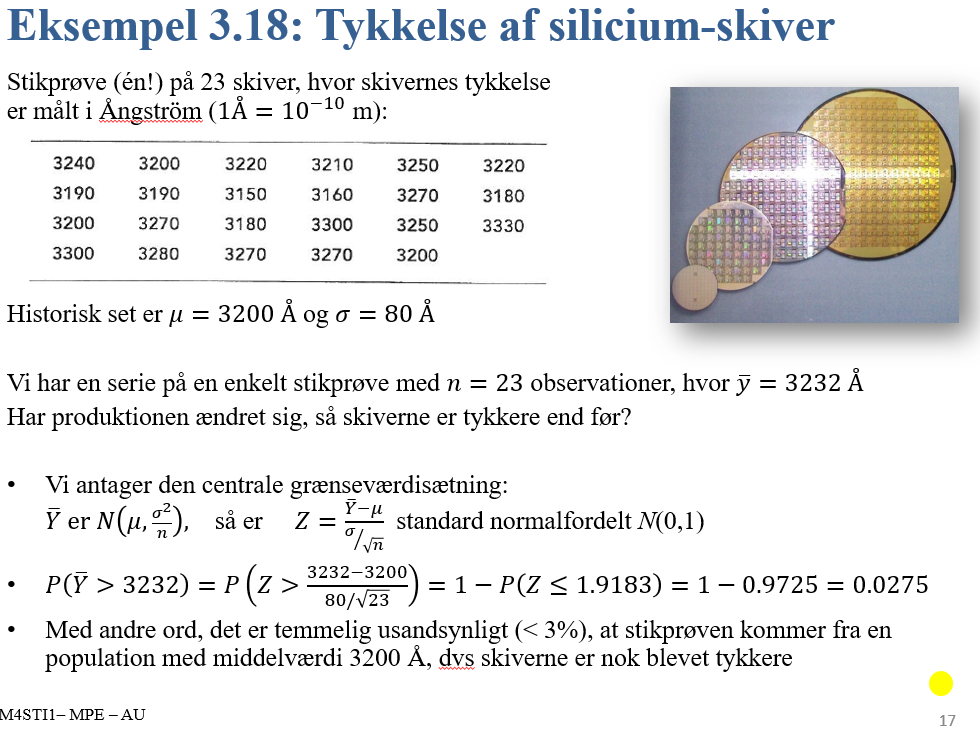

Ybar = mean_gns;
mu_obs = 3.5;
std_obs = 0.8;

(Ybar - mu_obs)/(std_obs*sqrt(stik))

ans = 0.7734